%addpath 'C:\Users\anonf\OneDrive\uni\phys project\matlab\iwave\development\matlab'

load_parameters

chunk_length = 2^21;
num_samples = chunk_length * 5;

t_end = t_step * (num_samples - 1) % secs

t_end = 0.0419

t = 0 : t_step : t_end;

%% generate axion frequency
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);

%plot(t, f_axion)
%yline([f_a - axion_linewidth/2, f_a + axion_linewidth/2])

%% generate signal and noise
signal = generate_axion_signal(t, f_sampling, f_axion, 0.7*axion_power);
noise_power = calculate_noise_power(f_sampling, 20e-3)

noise_power = 3.2959e-17

noise = generate_thermal_noise(t, noise_power);

x = signal + noise;
%x = noise;
%x = signal;

f_0 = f_a - 3e3

f_0 = 2.4175e+07

Q = 1e4;
y = resonator(x, f_0, f_0*ones(size(x)), Q, f_sampling);

num_chunks = 2;

% test for length
[f, pwr] = do_fft(y(1:chunk_length), f_sampling);

[f, pwr] = do_fft(y, f_sampling);

bin_width = f(2) - f(1)

bin_width = 476.8372

disp_width = 1e5;
start_index = find(f > f_0 - 0.15e5, 1);
end_index = find(f > f_0 + 0.15e5, 1);
%end_index = length(f)-1;
%start_index = find(f > f_0 - disp_width, 1);
%end_index = find(f > f_0 + disp_width, 1);
chop = start_index : end_index;

powers = pwr;

f_ = f(chop);
p_ = powers(chop);

omega_0 = 2*pi * f_0;
Delta_0 = omega_0 / f_sampling;
w = Delta_0 / (2 * Q);

Delta = 2*pi*f_/f_sampling;
A_Delta = (1 - exp(-w)) ./ sqrt(1 - 2*exp(-w)*cos(Delta - Delta_0) + exp(-2*w)); % from Ed paper
noise_model = A_Delta * 9.2e-13;

f__ = linspace(f_(1), f_(end), 200);
Delta_ = 2*pi*f__/f_sampling;
A_Delta_ = (1 - exp(-w)) ./ sqrt(1 - 2*exp(-w)*cos(Delta_ - Delta_0) + exp(-2*w)); % from Ed paper
noise_model_ = A_Delta_ * 9.2e-13;

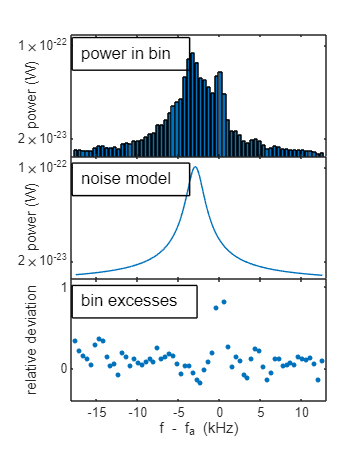

adstyle(8, 10)
tiledlayout(3,1, 'TileSpacing','none')

nexttile
bar((f_ - f_a)/1e3, p_ * 1.1e-10, 'HandleVisibility','off');
x_lim = xlim();
ylim([0.5e-23 1.1e-22])
ax = gca;
ax.YAxis.Exponent = 0;
ax.YAxis.TickValues = [2e-23 10e-23];
l = ylabel('power (W)');
l.Position(1) = -2.2e1;

nexttile
plot((f__ - f_a)/1e3, noise_model_ * 1.1e-10)
xlim(x_lim)
ylim([0.5e-23 1.1e-22])
ax = gca;
ax.YAxis.Exponent = 0;
ax.YAxis.TickValues = [2e-23 10e-23];
l = ylabel('power (W)');
l.Position(1) = -2.2e1;

nexttile
scatter((f_ - f_a)/1e3, (p_-noise_model)./noise_model, 80, '.')
xlabel('f - f_a (kHz)')
xlim(x_lim)
ax = gca;
ax.YAxis.Exponent = 0;
ax.YAxis.TickValues = [0 1];
ylim([-0.4 1.1])
l = ylabel('relative deviation');
l.Position(1) = -2.2e1;

box on

annotation('textbox', [0.2, 0.817, 0.1, 0.1], 'String', "power in bin", 'FontSize',10)
annotation('textbox', [0.2, 0.54, 0.1, 0.1], 'String', "noise model", 'FontSize',10, 'FitBoxToText','on')
annotation('textbox', [0.2, 0.27, 0.1, 0.1], 'String', "bin excesses", 'FontSize',10, 'FitBoxToText','on')

saveas(gca, 'figures/bins.eps', 'epsc')

f_0 = f_sampling/5000;

omega_0 = 2*pi * f_0;
Delta_0 = omega_0 / f_sampling;
Q = 1e4

Q = 10000

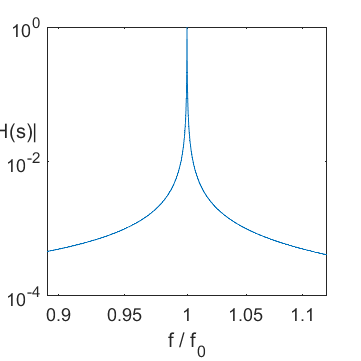

w = Delta_0 / (2 * Q);

f = logspace(-0.05, 0.05, 2001);

Delta = 2*pi*(f*f_0)/f_sampling;

A_Delta = (1 - exp(-w)) ./ sqrt(1 - 2*exp(-w)*cos(Delta - Delta_0) + exp(-2*w)); % from Ed paper
figure
adstyle(8, 8)
loglog(f, A_Delta)
yl = ylabel('|H(s)|');
yl.Rotation = 0;
yl.Position(2) = 0.03;
yl.VerticalAlignment = "middle";
yl.Position(1) = 0.885;
yl.HorizontalAlignment = "right";
xlabel('f / f_0')
saveas(gca, 'figures/filter.eps', 'epsc')


%xline([f_a - axion_linewidth/2, f_a + axion_linewidth/2])
%xline([f_0 - f_0/Q/2, f_0 + f_0/Q/2])


function [f, pwr] = do_fft(x, f_sampling)
    [pwr, f] = nsd_pwelch(x, 0.002, f_sampling);
    %figure
    %loglog(f, pwr)
end